# Partial Differential Equations

Partial differential equation is a class of differential equations involving more than one independent variable. In this chapter, we consider a general second-order PDE in two independent variables $x$ and $y$, which is written as


$$A\left(x,y\right)\frac{\partial^2 u}{{\partial x}^2 }+B\left(x,y\right)\frac{\partial^2 u}{\partial x\partial y}+C\left(x,y\right)\frac{\partial^2 u}{{\partial y}^2 }=f\left(x,y,u,\frac{\partial u}{\partial x},\frac{\partial u}{\partial y}\right)$$


for $x_0 \le x\le x_f$ and $y_0 \le y\le y_f$

with the boundary conditions given by 


$$u\left(x_0 ,y\right)=b_{\textrm{x0}} \left(y\right)$$



$$u\left(x_f ,y\right)=b_{\textrm{xf}} \left(y\right)$$



$$u\left(x,y_0 \right)=b_{\textrm{y0}} \left(x\right)$$



$$u\left(x,y_f \right)=b_{\textrm{yf}} \left(x\right)$$


These PDEs can be classified into three groups:

Elliptic PDE: if $B^2 -4\textrm{AC}<0$

Parabolic PDE: if $B^2 -4\textrm{AC}=0$

Hyperbolic PDE: if $B^2 -4\textrm{AC}>0$

## Hyperbolic PDE - One-dimensional Wave Equation

In this livescript, we consider the one-dimensional wave equation for the amplitude function $u\left(x,t\right)$, which is written as


$$A\frac{\partial^2 u\left(x,t\right)}{{\partial x}^2 }=\frac{\partial^2 u\left(x,t\right)}{{\partial t}^2 }$$


for $0\le x\le x_f$ and $0\le t\le T$

with the boundary conditions given by 


$$u\left(0,t\right)=b_0 \left(t\right)$$



$$u\left(x_f ,t\right)=b_{\textrm{xf}} \left(t\right)$$


and initial conditions given by


$$u\left(x,0\right)=i_0 \left(x\right)$$



$${\frac{\partial u\left(x,0\right)}{\partial t}}_{t=0} =i_0^{\prime } \left(x\right)$$


We apply the second derivatives on both sides by the three-point central difference approximation to get

$A\frac{u_{i+1}^k -2u_i^k +u_{i-1}^k }{{\Delta x}^2 }=\frac{u_i^{k+1} -2u_i^k +u_i^{k-1} }{{\Delta t}^2 }$ with $\Delta x=\frac{x_f }{M}$ and $\Delta t=\frac{T}{N}$

Here, we divide the spatial domain into $M$ and the temporal domain into $N$ sections. This equation can be rearranged into the following form


$$u_i^{k+1} =r\left(u_{i+1}^k +u_{i-1}^k \right)+2\left(1-r\right)u_i^k -u_i^{k-1}$$


where


$$r=A\frac{{\Delta t}^2 }{{\Delta x}^2 }$$
 

For stability $r\le 1$. The accuracy of the solution gets better as $r$ becomes larger so that $\Delta x$ decreases. It is therefore reasonable to select $r=1$.

If we use the rearranged equation on the initial time, $u_i^0$, we get this expression


$$u_i^1 =r\left(u_{i+1}^0 +u_{i-1}^0 \right)+2\left(1-r\right)u_i^0 -u_i^{-1}$$


Note that to get the next time step, $u_i^1$, we would need the "past" solution, $u_i^{-1}$, which we do not know. We can approximate the initial condition on the derivative by the central difference as


$${\frac{\partial u\left(x,0\right)}{\partial t}}_{t=0} =\frac{u_i^1 -u_i^{-1} }{2\Delta t}=i_0^{\prime } \left(x\right)$$


and rewrite this equation as

$u_i^{-1}$=$u_i^1 -2i_0^{\prime } \left(x\right)\Delta t$

We can then write


$$u_i^1 =r\left(u_{i+1}^0 +u_{i-1}^0 \right)+2\left(1-r\right)u_i^0 -\left(u_i^1 -2i_0^{\prime } \left(x\right)\Delta t\right)$$


or


$$u_i^1 =\frac{1}{2}r\left(u_{i+1}^0 +u_{i-1}^0 \right)+\left(1-r\right)u_i^0 +i_0^{\prime } \left(x\right)\Delta t$$


## Example 9.4. 1D Wave Equation

Consider the one-dimensional wave equation written as


$$\frac{\partial^2 u\left(x,t\right)}{{\partial x}^2 }=\frac{\partial^2 u\left(x,t\right)}{{\partial t}^2 }$$


for $0\le x\le 1$ and $0\le t\le 2$ 

with the boundary conditions


$$u\left(0,t\right)=0$$



$$u\left(1,t\right)=0$$


and the initial conditions


$$u\left(x,0\right)=x\left(1-x\right)$$



$$\frac{\partial u\left(x,0\right)}{\partial t}=0$$


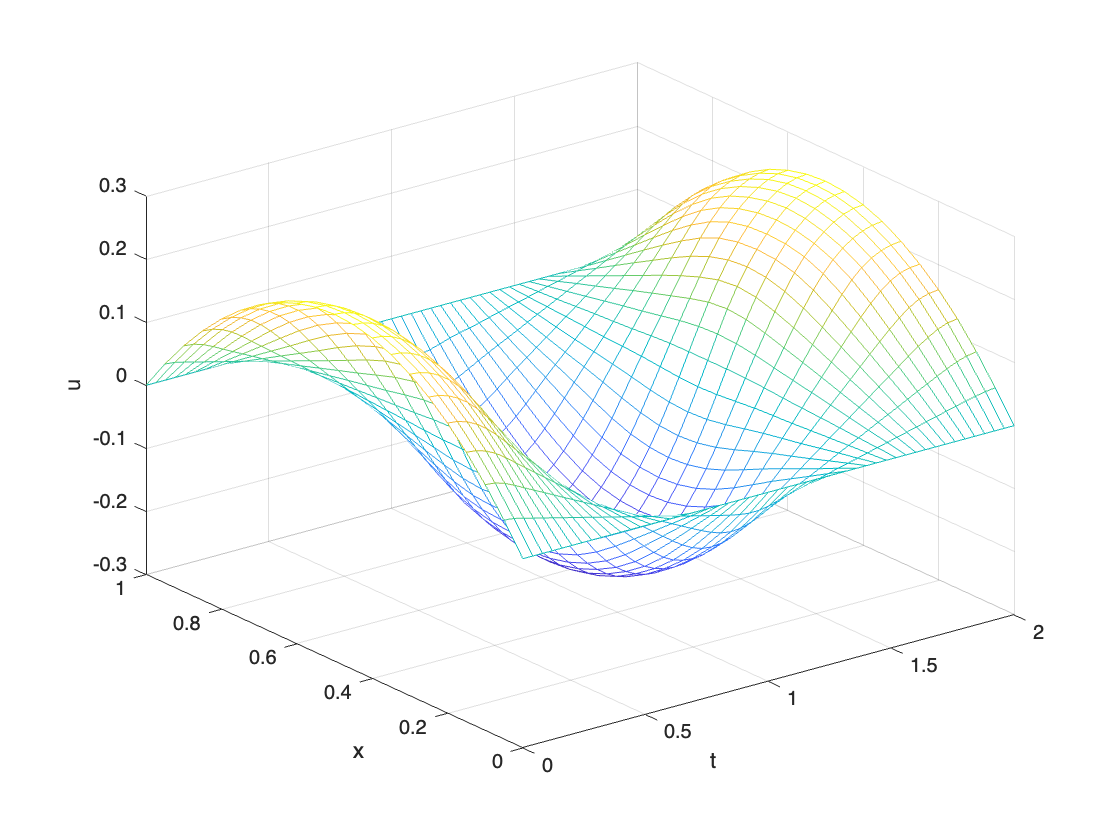

a = 1;
it0 = inline('x.*(1-x)','x'); i1t0 = inline('0'); %(E9.4.2a)
bx0t = inline('0'); bxft = inline('0'); %(E9.4.2b)
xf = 1; M = 20; T = 2; N = 50;
[u,x,t] = wave(a,xf,T,it0,i1t0,bx0t,bxft,M,N);
figure(1), clf
mesh(t,x,u)
xlabel('t'), ylabel('x'), zlabel('u')

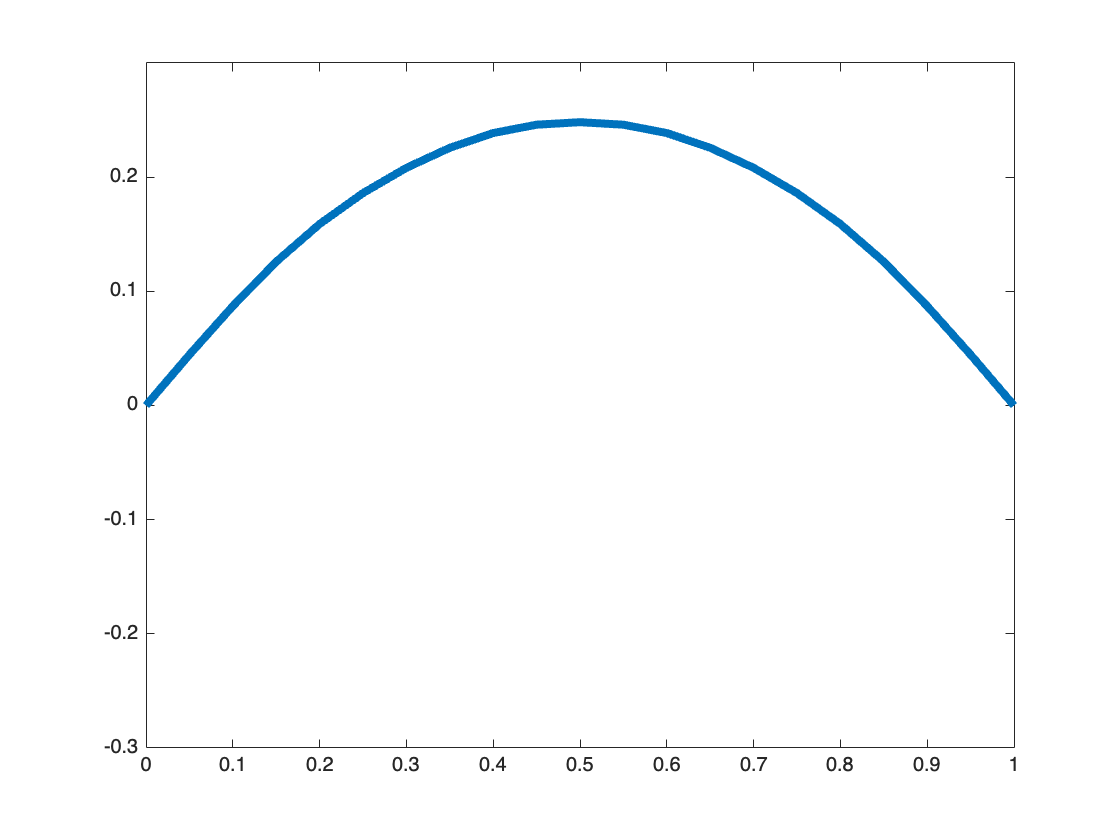

figure(2), clf
for n = 1:N %dynamic picture
    plot(x,u(:,n),'LineWidth',4), axis([0 xf -0.3 0.3]), pause(0.2)
end

## Two-Dimensional Hyperbolic PDE

We consider a two-dimensional wave equation for the amplitude function $u\left(x,y,t\right)$ written as


$$A\left(\frac{\partial^2 u\left(x,y,t\right)}{{\partial x}^2 }+\frac{\partial^2 u\left(x,y,t\right)}{{\partial y}^2 }\right)=\frac{\partial^2 u\left(x,t\right)}{{\partial t}^2 }$$


for $0\le x\le x_f$,$0\le y\le y_f$, and $0\le t\le T$

with the boundary conditions given by 


$$u\left(0,y,t\right)=b_{\textrm{x0}} \left(t\right)$$



$$u\left(x_f ,y,t\right)=b_{\textrm{xf}} \left(t\right)$$



$$u\left(x,0,t\right)=b_{\textrm{y0}} \left(t\right)$$



$$u\left(x,y_f ,t\right)=b_{\textrm{yf}} \left(t\right)$$


and initial conditions given by


$$u\left(x,y,0\right)=i_0 \left(x,y\right)$$



$${\frac{\partial u\left(x,y,0\right)}{\partial t}}_{t=0} =i_0^{\prime } \left(x,y\right)$$


Similar to the one-dimensional case, we apply the second derivatives on both sides by the three-point central difference approximation to get


$$A\left(\frac{u_{i,j+1}^k -2u_{i,j}^k +u_{i,j-1}^k }{{\Delta x}^2 }+\frac{u_{i+1,j}^k -2u_{i,j}^k +u_{i-1,j}^k }{{\Delta y}^2 }\right)=\frac{u_{i,j}^{k+1} -2u_{i,j}^k +u_{i,j}^{k-1} }{{\Delta t}^2 }$$


with $\Delta x=\frac{x_f }{M_x }$,$\Delta y=\frac{y_f }{M_y }$ and $\Delta t=\frac{T}{N}$

Here, we divide the spatial domain into $M_x$ and $M_y$ and the temporal domain into $N$ sections. This equation can be rearranged into the following form


$$u_{i,j}^{k+1} =r_x \left(u_{i,j+1}^k +u_{i,j-1}^k \right)+r_y \left(u_{i+1,j}^k +u_{i-1,j}^k \right)+2\left(1-r_x -r_y \right)u_{i,j}^k -u_{i,j}^{k-1}$$


where

$r_x =A\frac{{\Delta t}^2 }{{\Delta x}^2 }$ and $r_y =A\frac{{\Delta t}^2 }{{\Delta y}^2 }$ 

For stability, the sufficient condition is

$r=\frac{4A{\Delta t}^2 }{{\Delta x}^2 +{\Delta y}^2 }\le 1$. 

If we use the rearranged equation on the initial time, $u_{i,j}^0$, we get this expression


$$u_{i,j}^1 =r_x \left(u_{i,j+1}^0 +u_{i,j-1}^0 \right)+r_y \left(u_{i+1,j}^0 +u_{i-1,j}^0 \right)+2\left(1-r_x -r_y \right)u_{i,j}^0 -u_{i,j}^{-1}$$


Note that to get the next time step, $u_{i,j}^1$, we would need the "past" solution, $u_{i,j}^{-1}$, which we do not know. We can approximate the initial condition on the derivative by the central difference as


$${\frac{\partial u\left(x,y,0\right)}{\partial t}}_{t=0} =\frac{u_{i,j}^1 -u_{i,j}^{-1} }{2\Delta t}=i_0^{\prime } \left(x_j ,y_i \right)$$


and rewrite this equation as

$u_{i,j}^{-1}$=$u_{i,j}^1 -2i_0^{\prime } \left(x_j ,y_i \right)\Delta t$

We can then write


$$u_{i,j}^1 =\frac{1}{2}\left\lbrace r_x \left(u_{i,j+1}^0 +u_{i,j-1}^0 \right)+r_y \left(u_{i+1,j}^0 +u_{i-1,j}^0 \right)\right\rbrace +2\left(1-r_x -r_y \right)u_{i,j}^0 +i_0^{\prime } \left(x_j ,y_i \right)\Delta t$$


## Example 9.5. 2D Wave Equation over a Square Membrane

Consider the one-dimensional wave equation written as


$$\frac{1}{4}\left(\frac{\partial^2 u\left(x,y,t\right)}{{\partial x}^2 }+\frac{\partial^2 u\left(x,y,t\right)}{{\partial y}^2 }\right)=\frac{\partial^2 u\left(x,t\right)}{{\partial t}^2 }$$


for $0\le x\le 2$,$0\le y\le 2$ and $0\le t\le 2$ 

with the boundary conditions

$u\left(0,y,t\right)=0$, $u\left(2,y,t\right)=0$

$u\left(x,0,t\right)=0$, $u\left(x,2,t\right)=0$

and the initial conditions


$$u\left(x,0\right)=0\ldotp 1\;\sin \left(\pi x\right)\;\sin \left(\pi \frac{y}{2}\right)$$



$${\frac{\partial u\left(x,0\right)}{\partial t}}_{t=0} =0$$


Note that if we select $M_x =M_y =N=20$, then 


$$r=\frac{4A{\Delta t}^2 }{{\Delta x}^2 +{\Delta y}^2 }=\frac{4\left(\frac{1}{4}\right){\left(\frac{2}{20}\right)}^2 }{{\left(\frac{2}{20}\right)}^2 +{\left(\frac{2}{20}\right)}^2 }=\frac{1}{2}\le 1$$


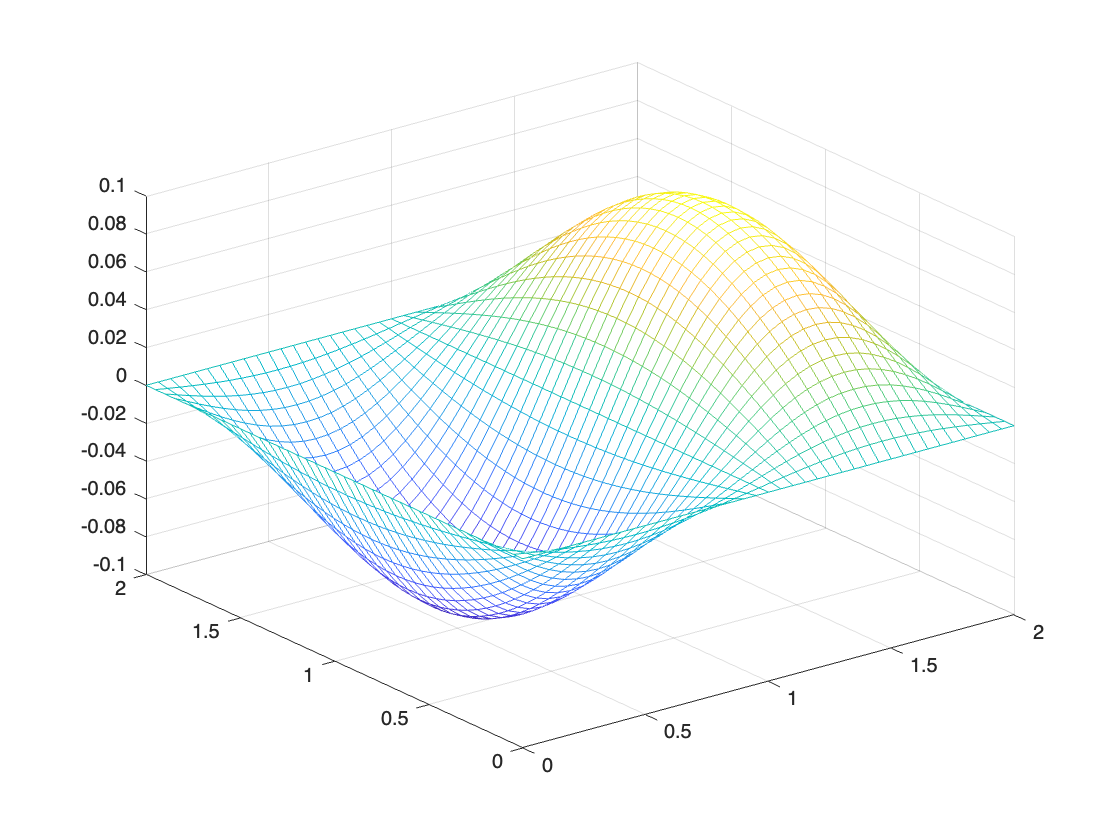

%solve_wave2
it0 = inline('0.1*sin(pi*x)*sin(pi*y/2)','x','y'); %(E9.5.3)
i1t0 = inline('0','x','y'); bxyt = inline('0','x','y','t'); %(E9.5.2)
a = .25; D = [0 2 0 2]; T = 2; Mx = 40; My = 40; N = 40;
[u,x,y,t] = wave2(a,D,T,it0,i1t0,bxyt,Mx,My,N);

Function for the 1D Wave Equation

function [u,x,t] = wave(a,xf,T,it0,i1t0,bx0,bxf,M,N)
    %solve a u_xx = u_tt for 0<=x<=xf, 0<=t<=T
    % Initial Condition: u(x,0) = it0(x), u_t(x,0) = i1t0(x)
    % Boundary Condition: u(0,t)= bx0(t), u(xf,t) = bxf(t)
    % M = # of subintervals along x axis
    % N = # of subintervals along t axis
    dx = xf/M; x = [0:M]'*dx;
    dt = T/N; t = [0:N]*dt;
    for i = 1:M + 1, u(i,1) = it0(x(i)); end
    for k = 1:N + 1
        u([1 M + 1],k) = [bx0(t(k)); bxf(t(k))];
    end
    r = a*(dt/dx)^ 2; r1 = r/2; r2 = 2*(1 - r);
    u(2:M,2) = r1*u(1:M - 1,1) + (1 - r)*u(2:M,1) + r1*u(3:M + 1,1) ...
    + dt*i1t0(x(2:M)); %Eq.(9.3.6)
    for k = 3:N + 1
        u(2:M,k) = r*u(1:M - 1,k - 1) + r2*u(2:M,k-1) + r*u(3:M + 1,k - 1)...
        - u(2:M,k - 2); %Eq.(9.3.3)
    end
end

Function for the 2D Wave Equation

function [u,x,y,t] = wave2(a,D,T,it0,i1t0,bxyt,Mx,My,N)
    %solve a(u_xx + u_yy) = u_tt for D(1) <= x <= D(2), D(3) <= y <= D(4), 0 <= t <= T
    % Initial Condition: u(x,y,0) = it0(x,y), u_t(x,y,0) = i1t0(x,y)
    % Boundary Condition: u(x,y,t) = bxyt(x,y,t) for (x,y) on Boundary
    % Mx/My = # of subintervals along x/y axis
    % N = # of subintervals along t axis
    dx = (D(2)- D(1))/Mx; x = D(1)+[0:Mx]*dx;
    dy = (D(4)- D(3))/My; y = D(3)+[0:My]'*dy;
    dt = T/N; t = [0:N]*dt;
    %Initialization
    u = zeros(My+1,Mx + 1); ut = zeros(My + 1,Mx + 1);
    for j = 2:Mx
        for i = 2:My
            u(i,j) = it0(x(j),y(i)); ut(i,j) = i1t0(x(j),y(i));
        end
    end
    adt2 = a*dt*dt; rx = adt2/(dx*dx); ry = adt2/(dy*dy);
    rxy1 = 1- rx - ry; rxy2 = rxy1*2;
    u_1 = u;
    for k = 0:N
        t = k*dt;
        for i = 1:My + 1 %Boundary condition
            u(i,[1 Mx + 1]) = [bxyt(x(1),y(i),t) bxyt(x(Mx + 1),y(i),t)];
        end
        for j = 1:Mx + 1
            u([1 My + 1],j) = [bxyt(x(j),y(1),t); bxyt(x(j),y(My + 1),t)];
        end
        if k == 0
            for i = 2:My
                for j = 2:Mx %Eq.(9.3.13)
                    u(i,j) = 0.5*(rx*(u_1(i,j - 1) + u_1(i,j + 1))...
                    +ry*(u_1(i - 1,j)+u_1(i + 1,j))) + rxy1*u(i,j) + dt*ut(i,j);
                end
            end
        else
            for i = 2:My
                for j = 2:Mx %Eq.(<eqnr>9.3.10)</eqnr>
                    u(i,j) = rx*(u_1(i,j - 1)+ u_1(i,j + 1))...
                    + ry*(u_1(i - 1,j) + u_1(i + 1,j)) + rxy2*u(i,j) -u_2(i,j);
                end
            end
        end
    u_2 = u_1; u_1 = u; %update the buffer memory
    mesh(x,y,u), axis([0 2 0 2 -.1 .1]), pause(0.2)
    end
end